clc;clear all

% s = tf('s'); 
% H = [1/(s+1) 1/(s+2);1/(s+3) 2/(s+4)];
% z = tzero(H)
% 
% H1 = evalfr(H,z(1));
% svd(H1)
% 
% sys = ss(H)
% A = sys.A;B = sys.B; C =sys.C;D = sys.D;
% rank([-A,-B;C,D])
% rank([z(1)*eye(4)-A,-B;C,D])



A = [0.975,0,0.042,0;
    0,0.977,0,0.044;
    0,0,0.958,0;
    0,0,0,0.956];

B = [0.0515,0.0016;
    0.0019,0.0447;
    0,0.0737;
    0.085,0];

C = [0.2,0,0,0;
    0,0.2,0,0];
D = zeros(2,2);
sys1 = ss(A,B,C,D,0.1);
z = tzero(sys1)

z =     1.0306
    0.8886


## unstable zeros


rank([-A,-B;C,D])

ans = 6

rank([z(1)*eye(4)-A,-B;C,D])

ans = 5


x0g = null([z(1)*eye(4)-A,-B;C,D])

x0g =     0.0000
   -0.0000
    0.5259
   -0.5070
   -0.4450
    0.5180



x0= x0g(1:4)

x0 =     0.0000
   -0.0000
    0.5259
   -0.5070


g = x0g(5:6);

A*x0+B*g

ans =     0.0000
   -0.0000
    0.5420
   -0.5226


z(1)*x0

ans =     0.0000
   -0.0000
    0.5420
   -0.5226


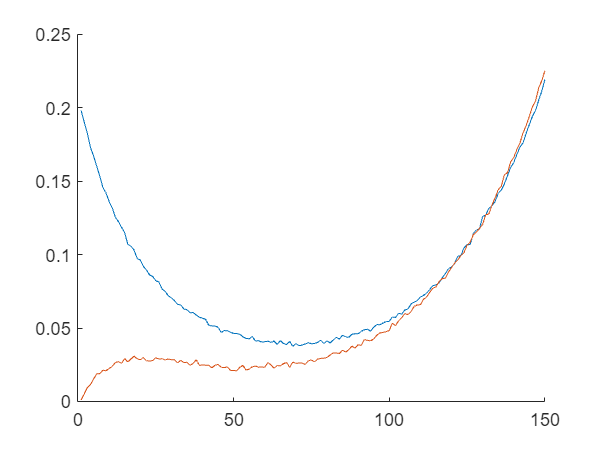


tspan = 150;
Q = eye(4);
R = eye(2);

K=-dlqr(A,B,Q,R);
x = zeros(4,tspan+1);
xh = zeros(4,tspan+1);
y = zeros(2,tspan);
r = zeros(2,tspan);
u = zeros(2,tspan);
x1 = [1;0;0;0];
x(:,1) = x1;

ua = zeros(2,tspan);
ya = zeros(2,tspan);
xa = zeros(4,tspan+1);
xa(:,1) = x0;


Qw = 0.001^2*eye(4);
Qv = 0.001^2*eye(2);
L1 = dlqr(A,C',Qw,Qv);
L = L1';

% L = 10^(-4)*[0.8349 0 0.2325 0;
%     0 0.8688 0 0.2292;
%     0.2325 0 0.5808 0;
%     0 0.2292 0 0.5557];

for k = 1:tspan
    ua(:,k) = z(1)^(k-1)*g;
    
%     ua(:,k) = zeros(2,1);
    u(:,k) = K*xh(:,k)+ua(:,k);


    wk = 0.001*randn(4,1);
    vk = 0.001*randn(2,1);

    xa(:,k+1) = A*xa(:,k)+B*ua(:,k);
    ya(:,k) = C*xa(:,k);

    x(:,k+1) = A*x(:,k)+B*u(:,k)+wk;
    y(:,k) = C*x(:,k)+vk;
    xh(:,k+1) = A*xh(:,k)+B*u(:,k)+L*(y(:,k) - C*x(:,k+1));
    r(:,k) = y(:,k) - C*x(:,k+1);

end

figure
hold on
plot(y(1,:))
plot(y(2,:))

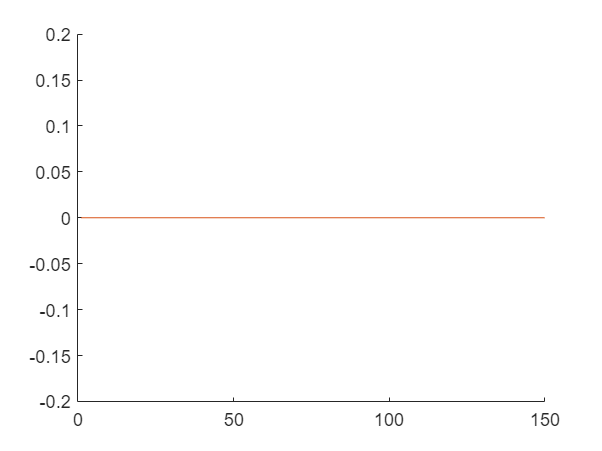


figure
hold on
plot(ya(1,:))
plot(ya(2,:))
ylim([-0.2,0.2])

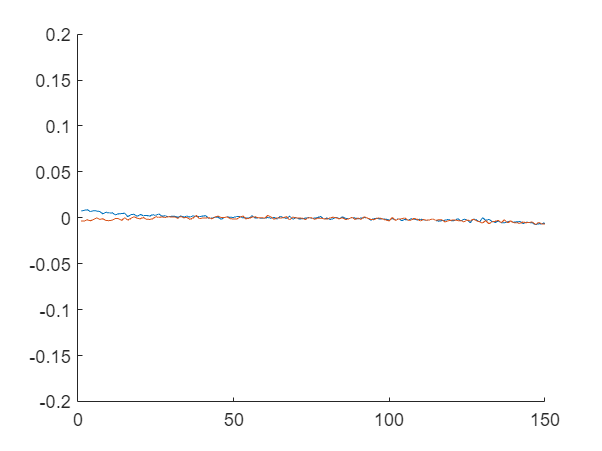


figure
hold on
plot(r(1,:))
plot(r(2,:))
ylim([-0.2,0.2])

% stable zeros
rank([-A,-B;C,D])

ans = 6

rank([z(2)*eye(4)-A,-B;C,D])

ans = 5


x0g = null([z(2)*eye(4)-A,-B;C,D])

x0g =    -0.0000
    0.0000
   -0.5354
   -0.5307
    0.4210
    0.5045



x0= x0g(1:4)

x0 =    -0.0000
    0.0000
   -0.5354
   -0.5307


g = x0g(5:6);

A*x0+B*g

ans =    -0.0000
    0.0000
   -0.4758
   -0.4715


z(2)*x0

ans =    -0.0000
    0.0000
   -0.4758
   -0.4715


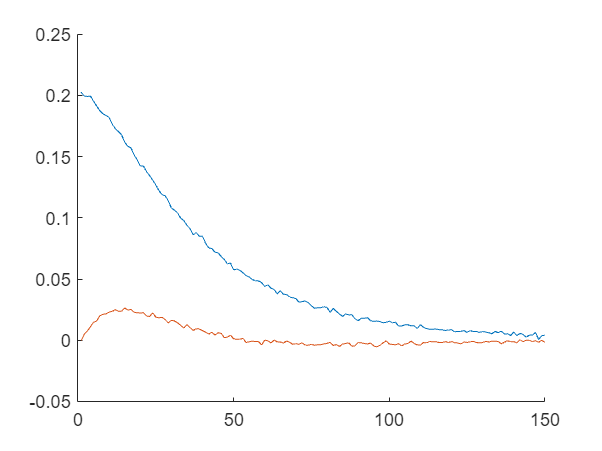


tspan = 150;
Q = eye(4);
R = eye(2);

K=-dlqr(A,B,Q,R);
x = zeros(4,tspan+1);
xh = zeros(4,tspan+1);
y = zeros(2,tspan);
r = zeros(2,tspan);
u = zeros(2,tspan);
x1 = [1;0;0;0];
x(:,1) = x1;

ua = zeros(2,tspan);
ya = zeros(2,tspan);
xa = zeros(4,tspan+1);
xa(:,1) = x0;


Qw = 0.001^2*eye(4);
Qv = 0.001^2*eye(2);
L1 = dlqr(A,C',Qw,Qv);
L = L1';

% L = 10^(-4)*[0.8349 0 0.2325 0;
%     0 0.8688 0 0.2292;
%     0.2325 0 0.5808 0;
%     0 0.2292 0 0.5557];

for k = 1:tspan
    ua(:,k) = z(2)^(k-1)*g;
    
%     ua(:,k) = zeros(2,1);
    u(:,k) = K*xh(:,k)+ua(:,k);


    wk = 0.001*randn(4,1);
    vk = 0.001*randn(2,1);

    xa(:,k+1) = A*xa(:,k)+B*ua(:,k);
    ya(:,k) = C*xa(:,k);

    x(:,k+1) = A*x(:,k)+B*u(:,k)+wk;
    y(:,k) = C*x(:,k)+vk;
    xh(:,k+1) = A*xh(:,k)+B*u(:,k)+L*(y(:,k) - C*x(:,k+1));
    r(:,k) = y(:,k) - C*x(:,k+1);

end

figure
hold on
plot(y(1,:))
plot(y(2,:))


figure
hold on
plot(ya(1,:))
plot(ya(2,:))
ylim([-0.2,0.2])

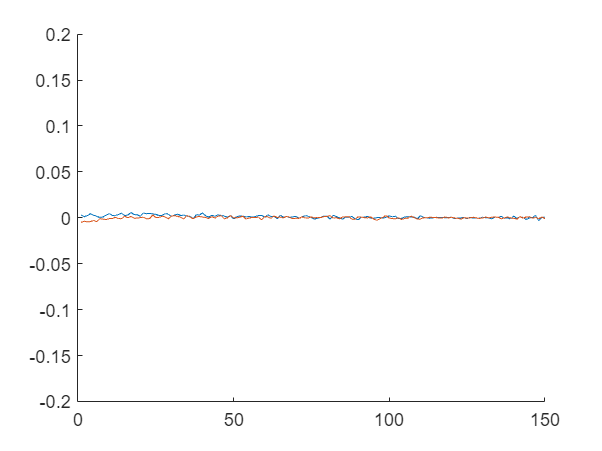


figure
hold on
plot(r(1,:))
plot(r(2,:))
ylim([-0.2,0.2])